clear;close all;clc; % 清空工作空间变量；关闭所有绘图；清空命令行

rosshutdown;

Shutting down global node /matlab_global_node_97917 with NodeURI http://Levanter-Jing-de-Dell:7462/
Shutting down ROS master on http://Levanter-Jing-de-Dell:11311/.


rosinit; % 初始化

Initializing ROS master on http://Levanter-Jing-de-Dell:11311/.
Initializing global node /matlab_global_node_73375 with NodeURI http://Levanter-Jing-de-Dell:7594/


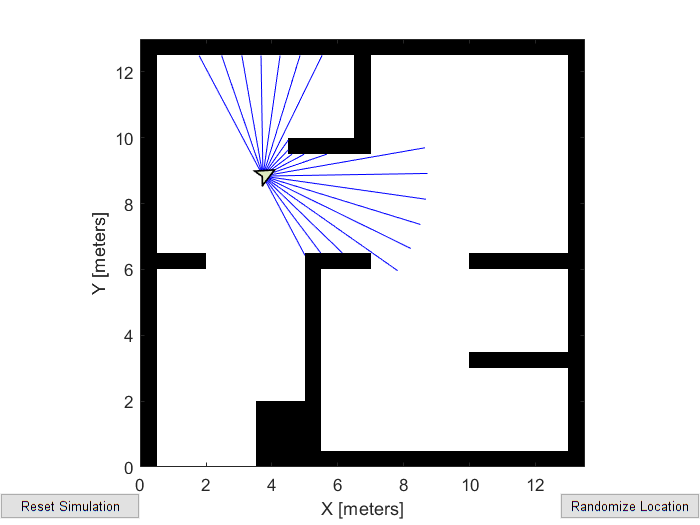

robotsim=ExampleHelperRobotSimulator('simpleMap');   % 创建一个机器人仿真环境，使用简单地图；
enableROSInterface(robotsim,true);   % 打开ROS接口；
pause(1); % 暂停，等待程序执行完毕

rostopic list; % 查看ROS网络中的所有topic

/ground_truth_pose            
/mobile_base/commands/velocity
/mobile_base/sensors/bumper   
/odom                         
/rosout                       
/scan                         
/tf                           
/tf_static                    


rostopic info /ground_truth_pose; % 查看某个topic的信息

Type: nav_msgs/Odometry
 
Publishers:
* /matlab_global_node_73375 (http://Levanter-Jing-de-Dell:7594/)
 
Subscribers:


# **Subscriber**

sub=rossubscriber('/ground_truth_pose'); % 创建 ROS Subscriber;

truth_pose=receive(sub,1);   % 接受 message
showdetails(truth_pose);   %显示 message 的详细内容


  ChildFrameId :  
  Header          
    Seq     :  4126
    FrameId :  
    Stamp      
      Sec  :  0
      Nsec :  0
  Pose            
    Covariance :  [0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0]
    Pose          
      Position       
        X :  12.95654343996709
        Y :  4.425014446659731
        Z :  0
      Orientation    
        X :  0
        Y :  0
        Z :  0.1335381657075868
        W :  0.9910436712372735
  Twist           
    Covariance :  [0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0, 0]
    Twist         
      Linear     
        X :  0
        Y :  0
        Z :  0
      Angular    
        X :  0
        Y :  0
        Z :  0


rosshutdown;